Zadanie 1

f= @(x) 0.2*x+0.6*sin(8*x)+(0.1*x.^2-0.5).^2;
x_0 = -4;  %punkt startowy
eps = 0.001; %epsilon
g2 = @(x) x - 4;
g1 = @(x) 0.2 - x;
c = 0.5; 
[x_min,c_l,i] = f_kar_zewn(f, x_0, c, eps, g1, g2)

x_min = 2.1554

c_l =      1     2


i = 2

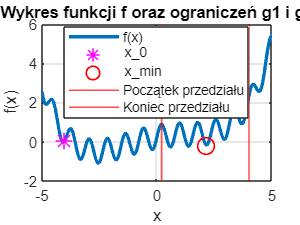

wykres(f, x_0, x_min, 0.2, 4)

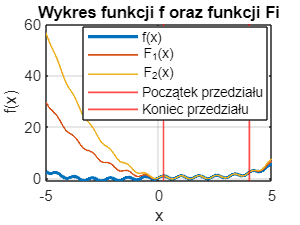

wykres_zewn(f, c_l,g1,g2, 0.2,4)

Zadanie 2

a) Punkt początkowy x0 = -1.3

f=@(x) 0.2*x+0.4*sin(4*x)+(0.1*x.^2-0.4).^2;
x_0 = -1.3;  %punkt startowy
eps = 0.001; %epsilon
g2 = @(x) x ;
g1 = @(x) -1.7 - x;
c = 0.5; 

[x_min,c_l,i] = f_kar_wewn(f, x_0,c, eps, g1,g2)

x_min = -1.6994

c_l =     0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005


i = 10

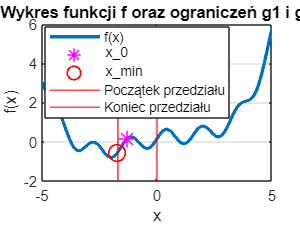

wykres(f, x_0, x_min, -1.7,0)

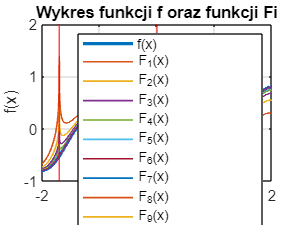

wykres_wewn(f, c_l,g1,g2, -1.7,0)

b) Punkt początkowy x0 = -1.123

x_0 = -1.123;  %punkt startowy
[x_min,c_l,i] = f_kar_wewn(f, x_0,c, eps, g1,g2)

x_min = -0.4354

c_l =     0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020


i = 8

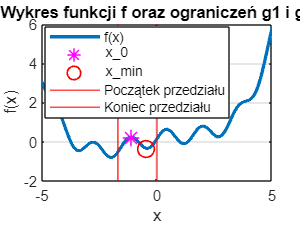


wykres(f, x_0, x_min, -1.7,0)

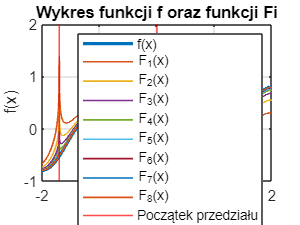

wykres_wewn(f, c_l,g1,g2, -1.7,0)

options = optimoptions('fmincon', 'Display','iter');
x0= -4;
A=[1;-1];
B=[4,-0.2];

fun = @(x) 0.2*x+0.6*sin(8*x)+(0.1*x.^2-0.5).^2

fun = function_handle with value:
    @(x)0.2*x+0.6*sin(8*x)+(0.1*x.^2-0.5).^2


x=fmincon(fun,x0,A,B,[],[],[],[],[],options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2    7.914399e-02    4.200e+00    2.420e+00
    1       4    7.083492e-02    2.427e+00    2.420e+00    1.773e+00
    2       6    8.814742e-01    0.000e+00    2.993e+00    2.442e+00
    3       8    8.401909e-01    0.000e+00    1.818e+00    3.409e-02
    4      11   -1.366340e-01    0.000e+00    1.494e+00    1.866e+00
    5      22   -1.606084e-01    0.000e+00    6.001e-01    5.860e-02
    6      24   -1.672837e-01    0.000e+00    5.420e-02    1.890e-02
    7      26   -1.672858e-01    0.000e+00    1.085e-02    3.145e-04
    8      28   -1.672858e-01    0.000e+00    1.085e-04    1.580e-05
    9      30   -1.672858e-01    0.000e+00    1.084e-06    1.609e-07
   10      32   -1.672858e-01    0.000e+00    1.084e-08    1.546e-09

Local minimum found that satisfies the cons

x = 2.1554

options = optimoptions('fmincon', 'Display','iter');
x0= -1.3;
A=[1;-1];
B=[0, 1.7];

fun = @(x) 0.2*x+0.4*sin(4*x)+(0.1*x.^2-0.4).^2

fun = function_handle with value:
    @(x)0.2*x+0.4*sin(4*x)+(0.1*x.^2-0.4).^2


x=fmincon(fun,x0,A,B,[],[],[],[],[],options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2    1.467429e-01    0.000e+00    3.410e-01
    1       4   -2.645639e-01    0.000e+00    1.043e+00    2.570e-01
    2       7   -3.984055e-01    0.000e+00    5.117e-01    7.113e-02
    3       9   -4.451367e-01    0.000e+00    6.052e-02    2.564e-02
    4      11   -5.015058e-01    0.000e+00    2.271e-02    3.210e-02
    5      13   -5.242025e-01    0.000e+00    7.334e-03    1.343e-02
    6      15   -5.251194e-01    0.000e+00    1.229e-04    5.498e-04
    7      17   -5.253223e-01    0.000e+00    1.245e-06    1.217e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

x = -1.7000

x=fmincon(fun,-1.123,A,B,[],[],[],[],[],options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2    2.407391e-01    0.000e+00    2.232e-02
    1       4    2.387079e-01    0.000e+00    1.555e-01    2.163e-02
    2       6   -2.938013e-01    0.000e+00    7.250e-01    7.835e-01
    3      10   -3.307178e-01    0.000e+00    2.498e-01    1.585e-01
    4      12   -3.360659e-01    0.000e+00    2.129e-03    4.097e-02
    5      14   -3.360682e-01    0.000e+00    1.000e-03    6.759e-04
    6      16   -3.360684e-01    0.000e+00    2.003e-04    1.829e-04
    7      18   -3.360684e-01    0.000e+00    2.022e-06    4.854e-05
    8      20   -3.360684e-01    0.000e+00    2.000e-08    4.899e-07

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


x = -0.4345

Zadania QUIZ

1)

f= @(x) 0.2*x+0.6*sin(8*x)+(0.1*x.^2-0.5).^2;
x_0 = -4;  %punkt startowy
eps = 0.001; %epsilon
g2 = @(x) x - 4;
g1 = @(x) 0.2 - x;
c = 0.5; 

[x_zewn,c_l,i] = f_kar_zewn(f, x_0, c, eps, g1, g2)

x_zewn = 2.1554

c_l =      1     2


i = 2


wykres(f, x_0, x_zewn, 0.2, 4)

wykres_zewn(f, c_l,g1,g2, 0.2,4)


options = optimoptions('fmincon', 'Display','iter');
A=[1;-1];
B=[4,-0.2];

x=fmincon(f,x0,A,B,[],[],[],[],[],options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2    3.462569e-01    1.500e+00    2.320e+00
    1       4    4.755354e-02    0.000e+00    4.098e+00    1.752e+00
    2       7   -9.494193e-02    0.000e+00    2.374e+00    1.765e+00
    3      12   -1.631536e-01    0.000e+00    3.792e-01    7.617e-02
    4      14   -1.672849e-01    0.000e+00    5.540e-02    1.484e-02
    5      16   -1.672858e-01    0.000e+00    1.084e-02    2.292e-04
    6      18   -1.672858e-01    0.000e+00    1.085e-04    1.643e-05
    7      20   -1.672858e-01    0.000e+00    1.084e-06    1.624e-07
    8      22   -1.672858e-01    0.000e+00    1.084e-08    1.478e-09

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


x = 2.1554

2) 

a)

f=@(x) 0.2*x+0.4*sin(4*x)+(0.1*x.^2-0.4).^2

f = function_handle with value:
    @(x)0.2*x+0.4*sin(4*x)+(0.1*x.^2-0.4).^2


x_0 = -1.123;  %punkt startowy
eps = 0.001; %epsilon
g2 = @(x) x ;
g1 = @(x) -1.7 - x;
c = 0.5; 

[x_wewn,c_l,i] = f_kar_wewn(f, x_0,c, eps, g1,g2)

x_wewn = -0.4354

c_l =     0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020


i = 8


wykres(f, x_0, x_wewn, -1.7,0)

wykres_wewn(f, c_l,g1,g2, -1.7,0)

A=[1;-1];
B=[0,1.7];

x=fmincon(f,x0,A,B,[],[],[],[],[],options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2    1.467429e-01    0.000e+00    3.410e-01
    1       4   -2.645639e-01    0.000e+00    1.043e+00    2.570e-01
    2       7   -3.984055e-01    0.000e+00    5.117e-01    7.113e-02
    3       9   -4.451367e-01    0.000e+00    6.052e-02    2.564e-02
    4      11   -5.015058e-01    0.000e+00    2.271e-02    3.210e-02
    5      13   -5.242025e-01    0.000e+00    7.334e-03    1.343e-02
    6      15   -5.251194e-01    0.000e+00    1.229e-04    5.498e-04
    7      17   -5.253223e-01    0.000e+00    1.245e-06    1.217e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

x = -1.7000

b)

f=@(x) 0.2*x+0.4*sin(4*x)+(0.1*x.^2-0.4).^2;
x_0 = -1.3;  %punkt startowy
eps = 0.001; %epsilon
g2 = @(x) x ;
g1 = @(x) -1.7 - x;
c = 0.5; 

[x_wewn,c_l,i] = f_kar_wewn(f, x_0,c, eps, g1,g2)

x_wewn = -1.6994

c_l =     0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005


i = 10

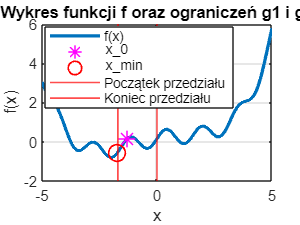


wykres(f, x_0, x_wewn, -1.7,0)

wykres_wewn(f, c_l,g1,g2, -1.7,0)

A=[1;-1];
B=[0,1.7];

x=fmincon(f,x0,A,B,[],[],[],[],[],options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2    1.467429e-01    0.000e+00    3.410e-01
    1       4   -2.645639e-01    0.000e+00    1.043e+00    2.570e-01
    2       7   -3.984055e-01    0.000e+00    5.117e-01    7.113e-02
    3       9   -4.451367e-01    0.000e+00    6.052e-02    2.564e-02
    4      11   -5.015058e-01    0.000e+00    2.271e-02    3.210e-02
    5      13   -5.242025e-01    0.000e+00    7.334e-03    1.343e-02
    6      15   -5.251194e-01    0.000e+00    1.229e-04    5.498e-04
    7      17   -5.253223e-01    0.000e+00    1.245e-06    1.217e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

x = -1.7000

function [x_ret, c_list,i] = f_kar_zewn(f, x_0,c, eps, g1,g2)
    i=0;
    x_prev = -Inf; % Inicjalizacja x i x_prev
    x = x_0;
    c_list=[];
    while (norm(x - x_prev) > eps)
        i=i+1;
        x_prev = x;
        S = @(xx) max(0,g1(xx)).^2 + max(0,g2(xx)).^2;
        F = @(xx) f(xx) + c * S(xx);
        x = fminsearch(F, x);
        c = 2 * c;
        c_list = [c_list,c];
    end
    x_ret = x;
end

function [x_ret, c_list,i] = f_kar_wewn(f, x_0,c, eps, g1,g2)
    i=0;
    x_prev = -Inf; % Inicjalizacja x i x_prev
    x = x_0;

    c_list=[];
    while (norm(x - x_prev) > eps) & (c*norm(- (log(-g1(x)) + log(-g2(x))))>=eps)
        i=i+1;
        x_prev = x;
        S = @(xx) - (log(-g1(xx)) + log(-g2(xx)));
        %S = @(xx) - (1/g1(xx)+1/g2(xx));
        F = @(xx) f(xx) + c * S(xx);
        x = fminsearch(F, x);
        c = 0.5 * c;
        c_list = [c_list,c];
    end
    x_ret = x;
end

function wykres(f, x_0, x_min, g1, g2)
    x_values = linspace(-5, 5, 1000);
    y_values = f(x_values);
    
    figure;
    plot(x_values, y_values, 'LineWidth', 2);
    
    hold on;
    plot(x_0, f(x_0), 'm*', 'MarkerSize', 10, 'LineWidth', 1);
    plot(x_min, f(x_min), 'ro', 'MarkerSize', 10, 'LineWidth', 1);


    xline(g1, 'r', 'LineWidth', 1);
    xline(g2, 'r', 'LineWidth', 1);
    
    legend('f(x)', 'x\_0', 'x\_min', 'Początek przedziału', 'Koniec przedziału', 'Location', 'Best');
    title('Wykres funkcji f oraz ograniczeń g1 i g2');
    xlabel('x');
    ylabel('f(x)');
    grid on;
    hold off;
end

function wykres_zewn(f, c_l, g1, g2, og_g1, og_g2)
    x_values = linspace(-5, 5, 1000);
    y_values = f(x_values);
    
    figure;
    plot(x_values, y_values, 'LineWidth', 2, 'DisplayName','f(x)');
    hold on;
    for i=1:length(c_l)
        S = @(xx) max(0,g1(xx)).^2 + max(0,g2(xx)).^2;
        F = @(xx) f(xx) + c_l(i) * S(xx);
        plot(x_values, F(x_values), 'LineWidth', 1, 'DisplayName', sprintf('F_{%d}(x)', i));
    end
    xline(og_g1, 'r', 'LineWidth', 1, 'DisplayName', 'Początek przedziału');
    xline(og_g2, 'r', 'LineWidth', 1, 'DisplayName', 'Koniec przedziału');
    legend('show', 'Location', 'Best');
    title('Wykres funkcji f oraz funkcji Fi');
    xlabel('x');
    ylabel('f(x)');
    grid on;
    hold off;
end

function wykres_wewn(f, c_l, g1, g2, og_g1, og_g2)
    x_values = linspace(-2, 2, 1000);
    y_values = f(x_values);
    
    figure;
    plot(x_values, y_values, 'LineWidth', 2, 'DisplayName','f(x)');
    hold on;
    for i=1:length(c_l)
        S = @(xx) - (log(-g1(xx)) + log(-g2(xx)));
        F = @(xx) f(xx) + c_l(i) * S(xx);
        plot(x_values, F(x_values), 'LineWidth', 1, 'DisplayName', sprintf('F_{%d}(x)', i));
    end
    xline(og_g1, 'r', 'LineWidth', 1, 'DisplayName', 'Początek przedziału');
    xline(og_g2, 'r', 'LineWidth', 1, 'DisplayName', 'Koniec przedziału');
    legend('show', 'Location', 'east');
    title('Wykres funkcji f oraz funkcji Fi');
    xlabel('x');
    ylabel('f(x)');
    grid on;
    hold off;
end